# Supply Chain Network Simulator

Designing the Supply Chain Network

clear all
close all
clc

rng(7)

caseNum = 2;

if caseNum == 1
    numOfChains = 2;            % Number of parallel chains
    numOfInventories = 3;       % Number of inventories in each chain
    matFile = 'Results/Case1/gridSearchCompleteDesignResults.mat';
elseif caseNum == 2
    numOfChains = 3;            % Number of parallel chains
    numOfInventories = 4;       % Number of inventories in each chain
    matFile = 'Results/Case2/gridSearchCompleteDesignResults.mat';
elseif caseNum == 3
    numOfChains = 4;            % Number of parallel chains
    numOfInventories = 5;       % Number of inventories in each chain
    matFile = 'Results/Case3/gridSearchCompleteDesignResults.mat';
end

% Create Network
netId = 1;               % Supply chain network ID
net = Network(netId, numOfChains, numOfInventories);

Started creating the supply chain network.
Started creating chain 1
Finished creating a chain...
Started creating chain 2
Finished creating a chain...
Started creating chain 3
Finished creating a chain...
Finished creating the supply chain network.


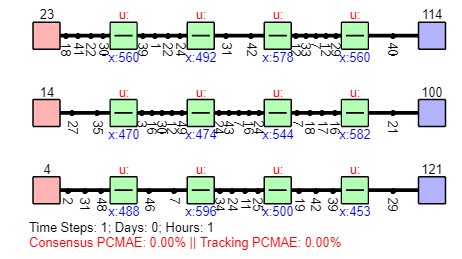

Figure saved as Results\PaperFigures\InitNetCase2.png and Results\PaperFigures\InitNetCase2.fig



% SCN setup and the initial condition
figNum = 1;
figure(figNum);
hold on; axis equal;  axis off;
net.draw(1);

% Save Fig
figWidth = 3.5; figHeight = 0; fontSize = 7;
fileName = ['InitNetCase',num2str(caseNum)];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);


tMax = 24*30 % 4 weeks

tMax = 720

saveMode = 3; % 1 FigSave, 2 vidSave, 3 display


% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)
% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks

d1 = 0;
d2 = -1; %-10
d3 = 0;
d4 = 0;
d5 = 1;
d6 = 0;
[pVal, deltaCostCoef, gammaCostCoef, comCostLimit] = net.findBestParameters(matFile,d1,d2,d3,d4,d5,d6) 

Error in c:
    0.2768   12.2999    0.0112       Inf    0.1296    0.1029

Best parameter combination found:
Minimum objective value: -0.90597
pVal: 0.031623
deltaCostCoef: 1000
gammaCostCoef: 100
comCostLimit: 0.01
LNorm: 1.3336
KNorm: 0.07368
gammaTilde: 209.8102
KLinks: 101
JCon: 25.8336
JTra: 50.0451


pVal = 0.0316

deltaCostCoef = 1000

gammaCostCoef = 100

comCostLimit = 0.0100


% d = [3.1623  0.0010  1.0000  0.1000];
% d = [0.0316    1000    100    0.01];
% d = [0.06    1000    100    0.01];
% pVal = d(1)
% deltaCostCoef = d(2)
% gammaCostCoef = d(3) %100
% comCostLimit = d(4)

save(['tempNet',num2str(caseNum)])
perfData.cumVals = [];
perfData.conHist = [];
perfData.traHist = [];
perfData.caseName{1} = 'CaseNames';
save('caseNum.mat','caseNum','perfData')

Local Steady State Control (LSSC): K = 0, L = 0

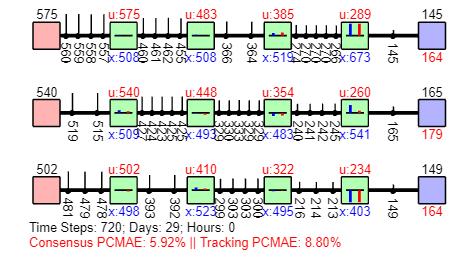

Figure saved as Results\PaperFigures\FinalNetCase2LSSC.png and Results\PaperFigures\FinalNetCase2LSSC.fig


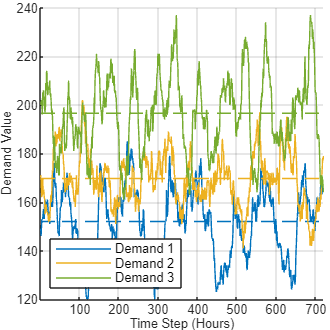

Figure saved as Results\PaperFigures\DemandsCase2.png and Results\PaperFigures\DemandsCase2.fig


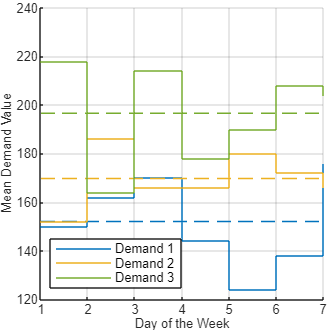

Figure saved as Results\PaperFigures\MeanDemandsCase2.png and Results\PaperFigures\MeanDemandsCase2.fig


clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'Steady';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    net.chains{i}.LLocal = 0*net.chains{i}.LLocal;
end
net.chains{1}.LLocal;
net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
% figNum = figNum + 1;
% figure(figNum); 
% hold on; axis equal; axis off;
% net.plotConnections(net.adjMat);

% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    % Save Fig
    figWidth = 3.5; figHeight = 0; fontSize = 7;
    fileName = ['FinalNetCase',num2str(caseNum),'LSSC'];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

    % % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);

    % % Demand Profile
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on; 
    net.plotDemandProfiles();
    axis([-inf,inf,120,240]);

    % Save Fig
    figWidth = 2.5; figHeight = 2.5; fontSize = 7;
    fileName = ['DemandsCase',num2str(caseNum)];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);


    % % Mean Demand Proile
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotMeanDemandProfiles();
    axis([-inf,inf,120,240]);

    % Save Fig
    figWidth = 2.5; figHeight = 2.5; fontSize = 7;
    fileName = ['MeanDemandsCase',num2str(caseNum)];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'LSSC';
save('caseNum.mat','caseNum','perfData')

Local State Feedback Control (LSFC): K = 0

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'NullGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    pVal = NaN;
    net.chains{i}.localControlDesign(pVal,deltaCostCoef);
end
net.chains{1}.LLocal

ans =    -0.5830   -0.6748   -0.7289   -0.5919   -0.6494   -0.6954   -0.6363   -0.7517   -0.8093   -0.8103   -0.8950   -0.9454   -1.0114   -0.6578   -0.7284   -0.8086
    0.0221   -0.3972   -0.3566   -0.3197    0.0306   -0.0829   -0.1987   -0.4431   -0.4352   -0.3967   -0.4312   -0.4841   -0.5175   -0.3559   -0.3816   -0.4490
   -0.1766   -0.0675   -0.3904   -0.3041   -0.1968   -0.2078   -0.2082   -0.0703   -0.1703   -0.4349   -0.4622   -0.4850   -0.4443   -0.3369   -0.3939   -0.4372
   -0.0982   -0.1325    0.0509   -0.2766   -0.1097   -0.1119   -0.1156   -0.1484   -0.1436    0.0628   -0.0524   -0.1363   -0.1750   -0.3083   -0.3264   -0.2845


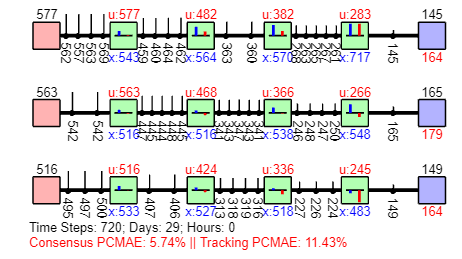

Figure saved as Results\PaperFigures\FinalNetCase2LSFC.png and Results\PaperFigures\FinalNetCase2LSFC.fig


net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
% figNum = figNum + 1;
% figure(figNum);
% hold on; axis equal; axis off;
% net.plotConnections(net.adjMat);

% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % Save Fig
    figWidth = 3.5; figHeight = 0; fontSize = 7;
    fileName = ['FinalNetCase',num2str(caseNum),'LSFC'];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);


    % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'LSFC';
save('caseNum.mat','caseNum','perfData')

Distributed Control with Hard Graph Constraints

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 0;

% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)

% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks
% d1 = 0;
% d2 = -1; %-10
% d3 = 1;
% d4 = 1;
% [pVal, deltaCostCoef, gammaCostCoef, comCostLimit, KLinks] = net.findBestParameters(matFile,d1,d2,d3,d4) 

%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 1.3336

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 209.8102

KNormVal = 2.0391e-05

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.2548   -0.2325   -0.1978   -0.1557   -0.2831   -0.3082   -0.3374   -0.2583   -0.2770   -0.2197   -0.2405   -0.2588   -0.2726   -0.1730   -0.1920   -0.2109
    0.2538   -0.2134   -0.1448   -0.1125    0.2820    0.0948    0.0219   -0.2371   -0.2591   -0.1609   -0.1712   -0.1812   -0.2005   -0.1250   -0.1346   -0.1451
   -0.0204    0.1462   -0.1903   -0.1512   -0.0226   -0.0247   -0.0253    0.1625    0.0461   -0.2114   -0.2282   -0.2487   -0.2716   -0.1680   -0.1823   -0.1978
   -0.0166   -0.0264    0.1837   -0.2297   -0.0184   -0.0139   -0.0117   -0.0294   -0.0239    0.2041    0.0700    0.0113   -0.0118   -0.2552   -0.2704   -0.2915


net.KGlobal

ans = 1.0e-04 *

         0         0         0         0         0         0         0         0         0         0         0         0
    0.0193    0.0095   -0.0035         0   -0.0161   -0.0038   -0.0003         0         0   -0.0051         0         0
   -0.0009    0.0195    0.0099   -0.0034         0   -0.0162   -0.0036   -0.0005         0         0   -0.0049         0
         0   -0.0011    0.0191    0.0074         0         0   -0.0162   -0.0032         0         0         0   -0.0060
         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0044   -0.0017   -0.0012         0    0.1382   -0.0880   -0.0063         0   -0.0343   -0.0023         0         0
         0   -0.0048   -0.0026   -0.0020    0.0024    0.1381   -0.0888   -0.0017         0   -0.0349   -0.0037   -0.0020
         0         0   -0.0110   -0.0179         0    0.0002    0.1165   -0.0201         0         0   -0.0428   -0.0250
         0     

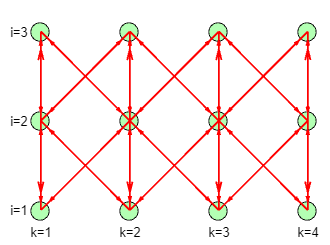

Figure saved as Results\PaperFigures\ReferenceTopologyCase2.png and Results\PaperFigures\ReferenceTopologyCase2.fig



% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMatRef);

% Save Fig
figWidth = 2.5; figHeight = 0; fontSize = 7;
fileName = ['ReferenceTopologyCase',num2str(caseNum)];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

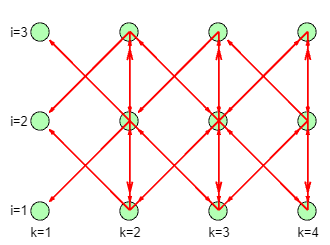

Figure saved as Results\PaperFigures\TopologyCase2DC-HGC.png and Results\PaperFigures\TopologyCase2DC-HGC.fig




% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

% Save Fig
figWidth = 2.5; figHeight = 0; fontSize = 7;
fileName = ['TopologyCase',num2str(caseNum),'DC-HGC'];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

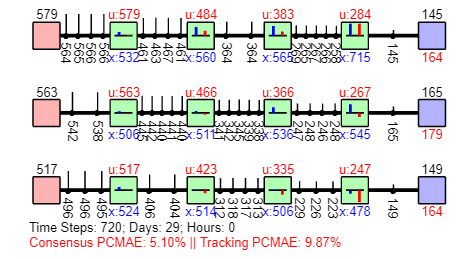

Figure saved as Results\PaperFigures\FinalNetCase2DC-HGC.png and Results\PaperFigures\FinalNetCase2DC-HGC.fig




% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    % Save Fig
    figWidth = 3.5; figHeight = 0; fontSize = 7;
    fileName = ['FinalNetCase',num2str(caseNum),'DC-HGC'];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);
    
    % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'DC-HGC';
save('caseNum.mat','caseNum','perfData')

Distributed Control with Soft Graph Constraints

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 1;

% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)

% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks
% d1 = 0;
% d2 = -1; %-10
% d3 = 1;
% d4 = 1;
% [pVal, deltaCostCoef, gammaCostCoef, comCostLimit, KLinks] = net.findBestParameters(matFile,d1,d2,d3,d4) 

%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 1.3336

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 209.8102

KNormVal = 0.0737

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.2548   -0.2325   -0.1978   -0.1557   -0.2831   -0.3082   -0.3374   -0.2583   -0.2770   -0.2197   -0.2405   -0.2588   -0.2726   -0.1730   -0.1920   -0.2109
    0.2538   -0.2134   -0.1448   -0.1125    0.2820    0.0948    0.0219   -0.2371   -0.2591   -0.1609   -0.1712   -0.1812   -0.2005   -0.1250   -0.1346   -0.1451
   -0.0204    0.1462   -0.1903   -0.1512   -0.0226   -0.0247   -0.0253    0.1625    0.0461   -0.2114   -0.2282   -0.2487   -0.2716   -0.1680   -0.1823   -0.1978
   -0.0166   -0.0264    0.1837   -0.2297   -0.0184   -0.0139   -0.0117   -0.0294   -0.0239    0.2041    0.0700    0.0113   -0.0118   -0.2552   -0.2704   -0.2915


net.KGlobal

ans =    -0.0422   -0.0022         0    0.0232   -0.0078         0         0    0.0155   -0.0039         0         0    0.0174
    0.0007   -0.0019         0         0    0.0002   -0.0001         0    0.0004    0.0001    0.0001         0    0.0005
    0.0003    0.0000   -0.0020    0.0006    0.0002         0         0    0.0001    0.0003    0.0001    0.0003    0.0000
    0.0003         0         0   -0.0007    0.0001    0.0001         0         0    0.0001         0         0    0.0001
   -0.0135         0         0    0.0115   -0.0197   -0.0005         0    0.0191   -0.0218         0         0    0.0249
         0         0         0         0    0.0002   -0.0002         0         0         0   -0.0001         0         0
         0         0         0         0         0    0.0001   -0.0001         0         0         0   -0.0001         0
    0.0001         0         0         0    0.0001         0         0   -0.0001    0.0001         0         0   -0.0002
   -0.0022         0      

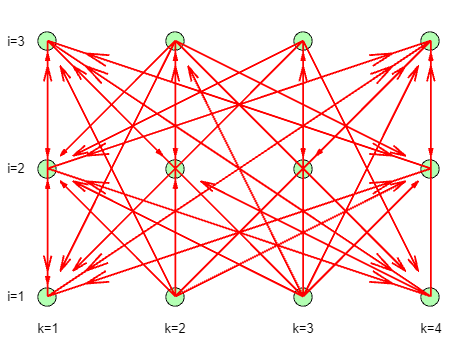

Figure saved as Results\PaperFigures\TopologyCase2DC-SGC.png and Results\PaperFigures\TopologyCase2DC-SGC.fig



% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off; 
net.plotConnections(net.adjMat);

% Save Fig
figWidth = 3.5; figHeight = 0; fontSize = 7;
fileName = ['TopologyCase',num2str(caseNum),'DC-SGC'];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

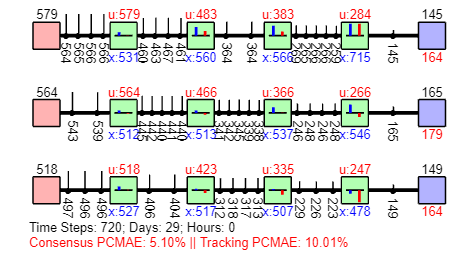

Figure saved as Results\PaperFigures\FinalNetCase2DC-SGC.png and Results\PaperFigures\FinalNetCase2DC-SGC.fig




% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    figWidth = 3.5; figHeight = 0; fontSize = 7;
    fileName = ['FinalNetCase',num2str(caseNum),'DC-SGC'];
    net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);

    
    % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'DC-SGC';
save('caseNum.mat','caseNum','perfData')

% perfData.cumVals
% What are the inventory capacities that will not limit controllers?
% How to improve tracking error performance without compromizing consensus
% error performance? - Change the local controller design approach....
% Local controllers being overly strong might be causing the osillatory
% behavior, - high control inputs causing overshoots...
% Is there an additional condition on KGlobal for conesensus_tracking
% (e.g., K*1 = 0?, read consensus notes/discussion)

Summary Plots (for the paper)

% A = [40.4448	26.9191; 34.4617	22.8563]
perfData.cumVals

ans =    44.0053   29.6084
   57.1586   28.7067
   49.3657   25.5117
   50.0318   25.4765



close all
clc

conHist = perfData.conHist;
traHist = perfData.traHist;
caseNames = perfData.caseName;
numCases = size(conHist,1);

L = size(conHist,2);

figNum = figNum + 1;
figure(figNum);
hold on; grid on; axis tight;
for k = 1:numCases
    plot(1:L, conHist(k,:), '-', 'DisplayName', caseNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t)); 
end
axis([0,L,0,50])
xlabel('Time Step (Hours)');
ylabel('Mean Per. Abs. Consensus Error (%)');
legend('Location', 'northeast');  
percentageImprovement = sum(conHist(end-1,:)>=conHist(end,:))*100/L

percentageImprovement = 60.9722

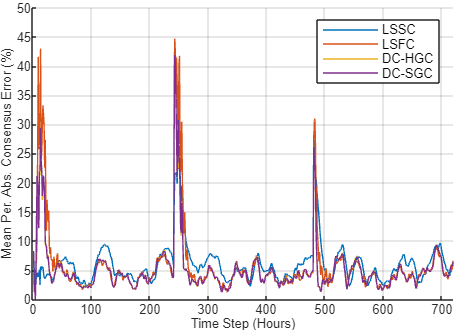

Figure saved as Results\PaperFigures\ConPerfCase2.png and Results\PaperFigures\ConPerfCase2.fig



figWidth = 3.5; figHeight = 2.5; fontSize = 7;
fileName = ['ConPerfCase',num2str(caseNum)];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);



figNum = figNum + 1;
figure(figNum);
hold on; grid on; axis tight;
for k = 1:numCases
    plot(1:L, traHist(k,:), '-', 'DisplayName', caseNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t));     
end
axis([0,L,0,100])
xlabel('Time Step (Hours)');
ylabel('Mean Perc. Abs. Tracking Error (%)');
legend('Location', 'northeast'); 
percentageImprovement = sum(traHist(end-1,:)>=traHist(end,:))*100/L

percentageImprovement = 21.5278

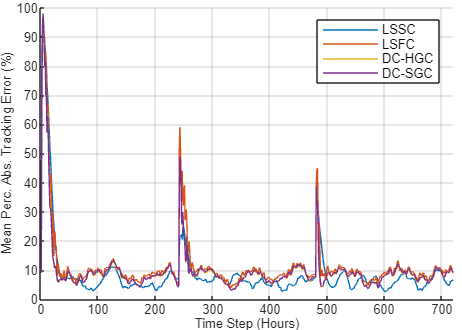

Figure saved as Results\PaperFigures\TraPerfCase2.png and Results\PaperFigures\TraPerfCase2.fig



figWidth = 3.5; figHeight = 2.5; fontSize = 7;
fileName = ['TraPerfCase',num2str(caseNum)];
net.saveFormattedFigure(gcf, 'Results/PaperFigures', fileName, figWidth, figHeight, fontSize);



net.printDefaultProperties()

Supply Chain Network Default Parameters:

--- Supply Class ---
supRateMax: 100000.000000

--- Demand Class ---
dailyMeans Obtained using: 100 + 20*randi([1,numOfChains],7,1) + 20*demId;
Chain 1.000000
dailyMeans:    150
   162
   170
   144
   124
   138
   176

demRateMean (mean): 152.000000
demRateStd (0.1x): 15.200000
Chain 2.000000
dailyMeans:    152
   186
   166
   166
   180
   172
   166

demRateMean (mean): 169.714286
demRateStd (0.1x): 16.971429
Chain 3.000000
dailyMeans:    218
   164
   214
   178
   190
   208
   204

demRateMean (mean): 196.571429
demRateStd (0.1x): 19.657143

--- Inventory Class ---
refLevel: 500.000000
maxLevel: 1000.000000
minLevel: 10.000000
perishRate: 0.100000
wasteRateMean Obtained using: 5 + randi([1,5])
wasteRateStd Obtained using: 0.2*mean
Chain 1.000000, Inventory 1.000000
wasteRateMean: 20.000000
wasteRateStd (0.2x): 4.000000
Chain 1.000000, Inventory 2.000000
wasteRateMean: 20.000000
wasteRateStd (0.2x): 4.000000
Chain 1.000000, Inventory 3.0